clear; close all; clc

syms z r theta

%% ==============================
%  TRANSFORMATION MATRICES
% ===============================

T_0_1 = [1 0 0 0;
         0 1 0 0;
         0 0 1 z;
         0 0 0 1];

T_1_2 = [cos(theta), -sin(theta), 0, 0;
         sin(theta),  cos(theta), 0, 0;
         0         ,  0         , 1, 0;
         0         ,  0         , 0, 1];

T_2_3 = [1 0 0 r;
         0 1 0 0;
         0 0 1 0;
         0 0 0 1];


## REQUIREMENT 1: Visualize Forward Kinematics

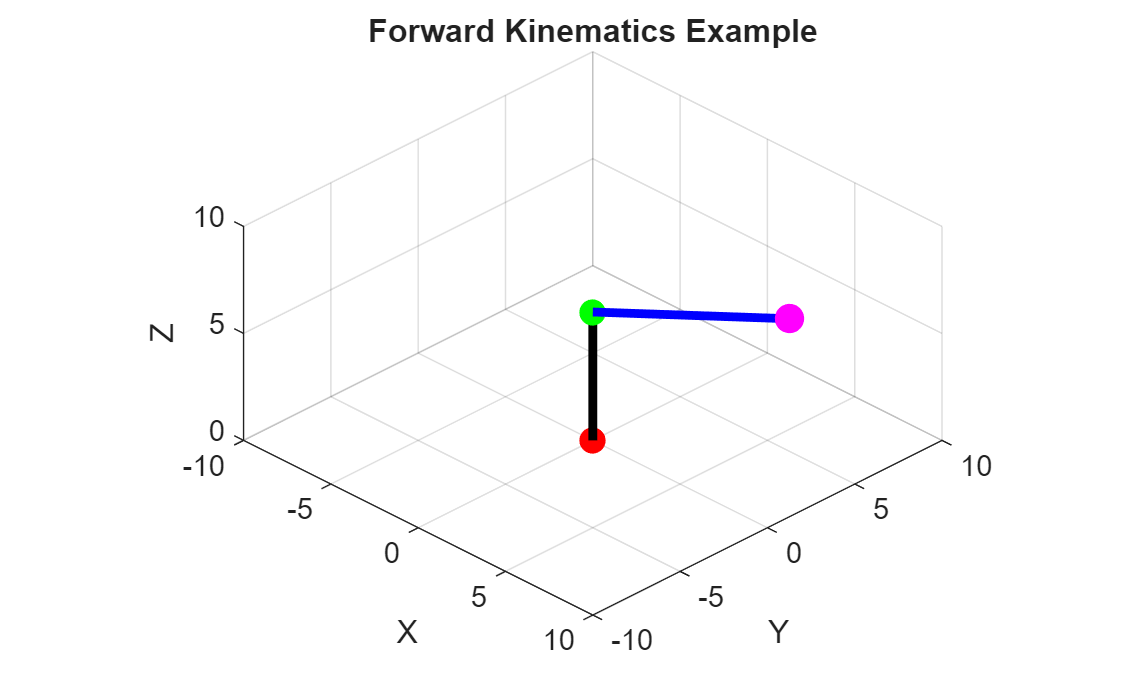


% this is separate, just confirming that our transformation matrices above
% work. 
%T_total = T_0_1 * T_1_2 * T_2_3
%T_eval = subs(T_total, {z, theta, r}, {6, 7, 8})
%pf = T_eval*[0;0;0;1]
%scatter3(pf(1), pf(2), pf(3), 'LineWidth', 5)
%hold on

% disclaimer: since thhis robot is purely cylindrical, the use of matrices
% is not strictly needed. It is sufficient for us to convert between
% cartesian and cylindrical coordinates. 

figure('Name','Forward Kinematics')


plot_robot(6, 7, 8) % <-- input joint variables
title('Forward Kinematics Example')

drawnow

% this function plots the robot based on given joint variables. 
function plot_robot(z, theta, r)

    clf
    hold on

    O0 = [0; 0; 0];
    O1 = [0; 0; z];
    O2 = O1;
    O3 = [r*cos(theta); r*sin(theta); z];

    plot3([O0(1) O1(1)], [O0(2) O1(2)], [O0(3) O1(3)], 'k', 'LineWidth', 3)
    plot3([O2(1) O3(1)], [O2(2) O3(2)], [O2(3) O3(3)], 'b', 'LineWidth', 3)

    scatter3(O0(1),O0(2),O0(3),80,'filled','r')
    scatter3(O1(1),O1(2),O1(3),80,'filled','g')
    scatter3(O3(1),O3(2),O3(3),100,'filled','m')

    axis equal
    grid on
    xlabel('X'); ylabel('Y'); zlabel('Z')
    xlim([-10 10]); ylim([-10 10]); zlim([0 10])
    view(45,30)

    hold off
end

## REQUIREMENT 2: Reachable Workspace (Point Cloud)

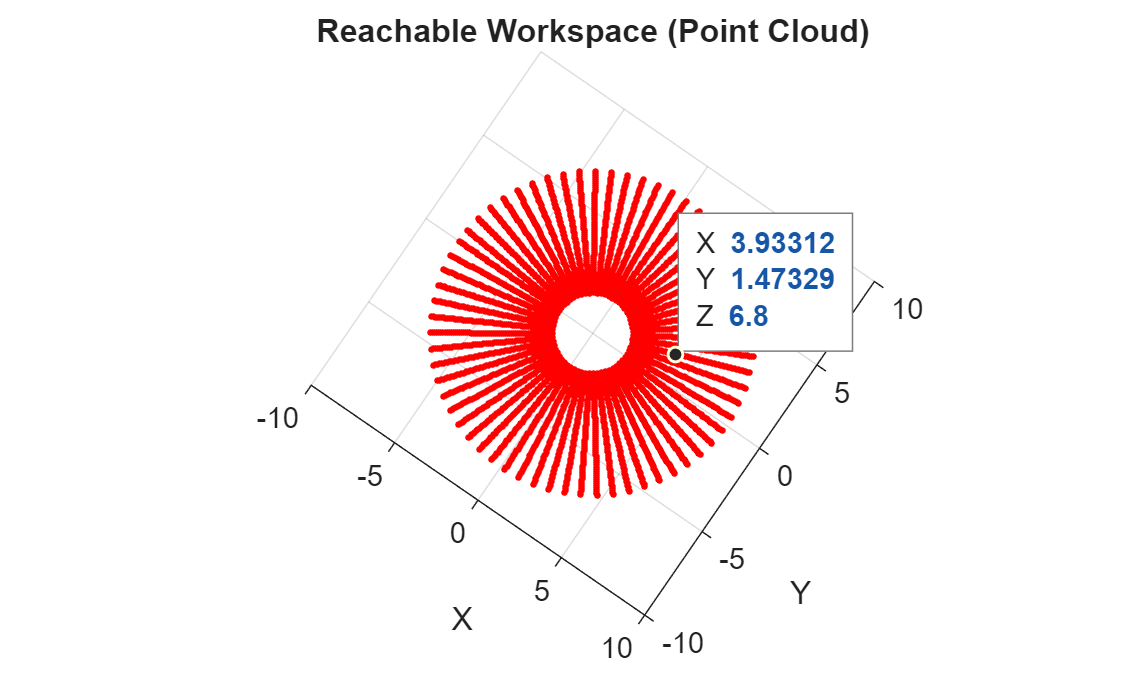



figure('Name','Workspace Point Cloud')
axis equal
grid on
xlabel('X'); ylabel('Y'); zlabel('Z')
xlim([-10 10]); ylim([-10 10]); zlim([0 10])
view(45,30)
hold on

theta_vals = -pi:0.1:pi;    % This method only iterates by 0.1 so our computers can run. 
r_vals = 2:0.1:8;
z_vals = 0:0.1:10;

[Theta, R, Z] = meshgrid(theta_vals, r_vals, z_vals);

% cylindrical to cartesian coordinates
X = R .* cos(Theta);
Y = R .* sin(Theta);

scatter3(X(:), Y(:), Z(:), 5, 'r', 'filled')
title('Reachable Workspace (Point Cloud)')
drawnow
hold off

## REQUIREMENT 3: Clean Workspace Envelope (Surfaces)

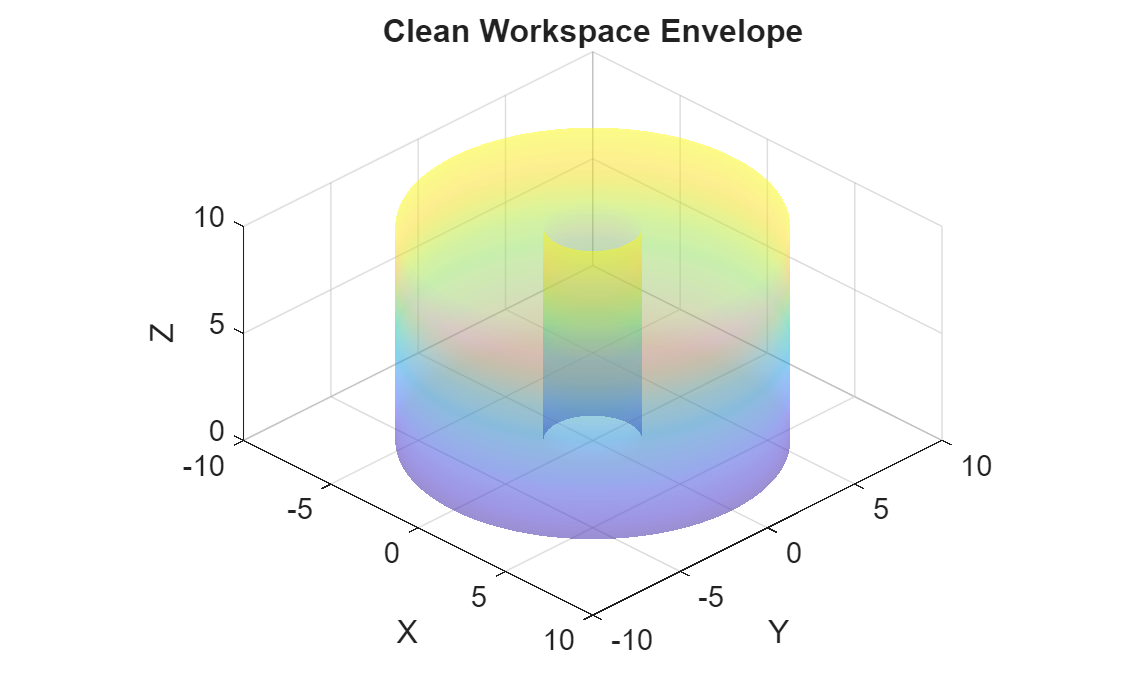

% This method also plots the work envelope, but in a nicer way using
% surfaces only. 

figure('Name','Workspace Envelope')
axis equal
grid on
xlabel('X'); ylabel('Y'); zlabel('Z')
xlim([-10 10]); ylim([-10 10]); zlim([0 10])
view(45,30)
hold on

theta_vals = linspace(-pi, pi, 100);
z_vals = linspace(0, 10, 100);
[Theta, Z] = meshgrid(theta_vals, z_vals);

% Outer cylinder
R = 8;
X = R*cos(Theta);
Y = R*sin(Theta);
surf(X, Y, Z, 'FaceAlpha', 0.3, 'EdgeColor', 'none')

% Inner cylinder
R = 2;
X = R*cos(Theta);
Y = R*sin(Theta);
surf(X, Y, Z, 'FaceAlpha', 0.3, 'EdgeColor', 'none')

% Top and bottom caps
r_vals = linspace(2, 8, 100);
theta_vals = linspace(-pi, pi, 100);
[R, Theta] = meshgrid(r_vals, theta_vals);

% cylindrical to cartesian coordinates
X = R .* cos(Theta);
Y = R .* sin(Theta);

surf(X, Y, 10*ones(size(X)), 'FaceAlpha', 0.3, 'EdgeColor', 'none')
surf(X, Y, zeros(size(X)), 'FaceAlpha', 0.3, 'EdgeColor', 'none')

title('Clean Workspace Envelope')
drawnow
hold off

## REQUIREMENT 4: Inverse Kinematics

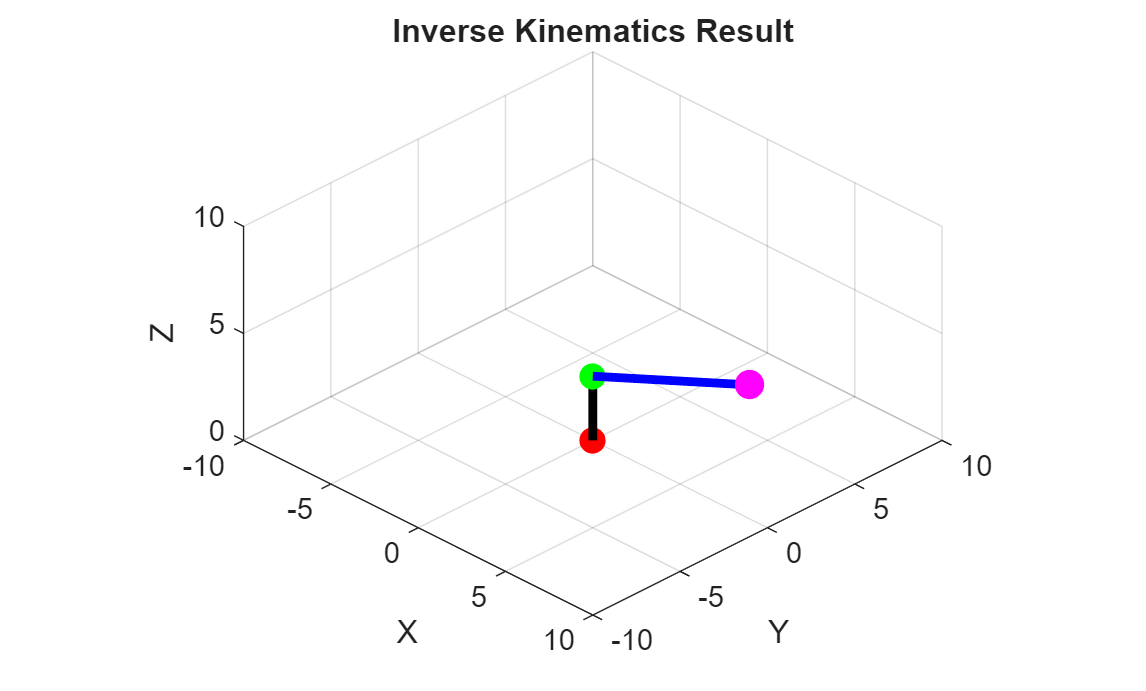

    3.0000    0.6747    6.4031





figure('Name','Inverse Kinematics Test')

[z_sol, theta_sol, r_sol, isValid] = ik_cylindrical(5, 4, 3);

% The isValid condition checks if all joint parameters are within the
% limits of the robot. If not, the program stops. 
if isValid
    plot_robot(z_sol, theta_sol, r_sol);
    title('Inverse Kinematics Result')
    disp([z_sol, theta_sol, r_sol])
end

drawnow

function [z_out, theta, r, isValid] = ik_cylindrical(x, y, z)

    % converting cartesian to cylindrical coordinates
    r = sqrt(x^2 + y^2);
    theta = atan2(y, x);
    z_out = z;

    z_lim     = [0, 10];
    theta_lim = [-pi, pi];
    r_lim     = [2, 8];

    % checking if the request is within the physical limits of the robot. 
    isValid = ...
        z_out >= z_lim(1) && z_out <= z_lim(2) && ...
        theta >= theta_lim(1) && theta <= theta_lim(2) && ...
        r >= r_lim(1) && r <= r_lim(2);

    if ~isValid
        warning('Target position is outside robot workspace');
    end
end

